% --- Vehicle Parameters ---

Mv = 280;                       % Vehicle Mass                       (kg)
r = 0.203;                      % Wheel Radius                       (m)
J = 1.2;                        % ESTIMATED Total Rotational Inertia (kg*m^2)
fd = 4;                         % Final Drive motor:tire             (Ratio)
h_cg = 0.262;                   % Height of Center of Gravity        (m)
W = 1.5494;                     % Wheelbase                          (m)


% --- Aerodynamics ---
A = 1.1;                        % Frontal Area                       (m^2)
rho = 1.225;                    % Air Density                        (kg/m^3)
Cd = 1.1;                       % Drag Coefficient
Cl = 3;                         % Lift Coefficient

% -- Static Loads --
F_zrs = (Mv * 9.80665) / 2;     % Static Normal Force on Rear Axle   (N)

% -- Control Params --
T_request = 150;                % Initial Driver Torque Request      (Nm)
Slip_Target = 0.2;              % Target Slip Ratio
Max_Wheel_Omega = 183;          % Maximum Wheel Angular Velocity     (rad/s)
Max_Motor_Torque = 150;         % Maximum Motor Torque               (rad/s)



% -- Simulink --
timedomain = 10;                % Simulation Time (s)
simout = sim("TC_SIM.slx", timedomain);

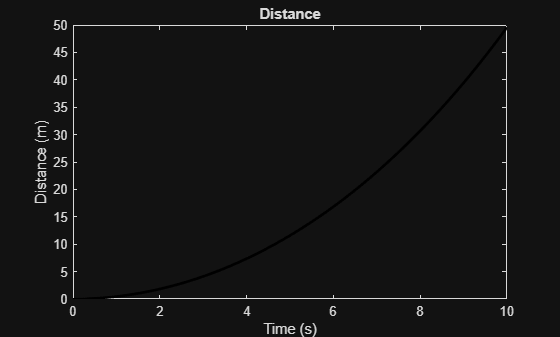


% -- Time and Data --
Time = simout.v_velocity.Time;           % Time Vector                   (s)
Wheel_Speed = simout.wheel_speed.Data;   % Wheel Speed                   (m/s)
Lift = simout.v_lift.Data;               % Vechile Lift                  (N)
Drag = simout.v_drag.Data;               % Vechile Drag                  (N)
Trac = simout.trac.Data;                 % Tractive Force                (N)
Accel = simout.v_accel.Data;             % Vechicle Accel                (m/s^2)
Vel = simout.v_velocity.Data;            % Vechicle Velocity             (m/s)
Dist = simout.v_distance.Data;           % Vechicle Distance             (m)
Motor_Tor = simout.T_motor.Data;         % Motor Torque                  (Nm)
Normal_Force = simout.normal_force.Data; % Normal Force on the rear axel (N)
Error = simout.error.Data;               % PID Error
Mu = simout.mu.Data;                     % Friction Coefficient
Slip_Ratio = simout.slip_ratio.Data;     % Slip Ratio



figure;
plot(Time, Dist, 'k', 'LineWidth', 2);
title('Distance');
xlabel('Time (s)');
ylabel('Distance (m)');

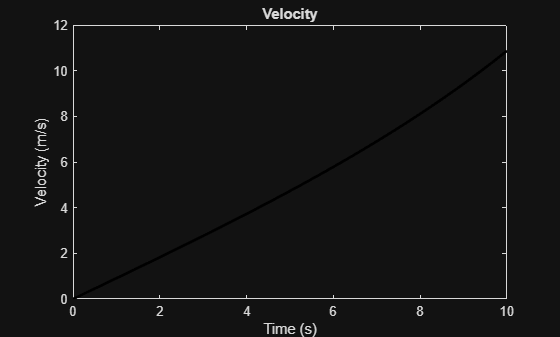


figure;
plot(Time, Vel, 'k', 'LineWidth', 2);
title('Velocity');
xlabel('Time (s)');
ylabel('Velocity (m/s)');

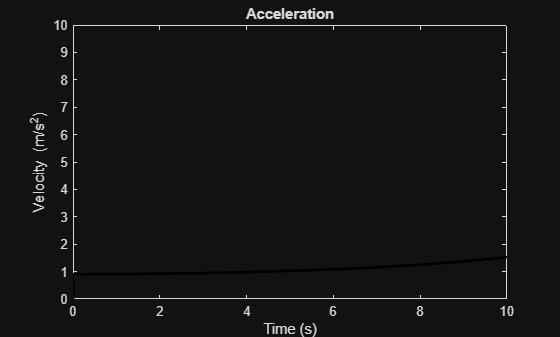


figure;
plot(Time, Accel, 'k', 'LineWidth', 2);
title('Acceleration');
xlabel('Time (s)');
ylabel('Velocity (m/s^2)');
ylim([0, 10])

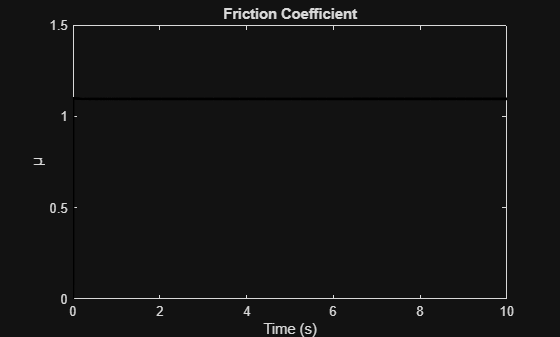


figure;
plot(Time, Mu, 'k', 'LineWidth', 2);
title('Friction Coefficient');
xlabel('Time (s)');
ylabel('μ');
ylim([0, 1.5])

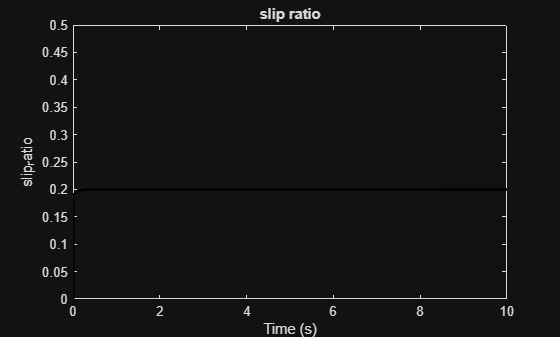


figure;
plot(Time, Slip_Ratio, 'k', 'LineWidth', 2);
title('slip ratio');
xlabel('Time (s)');
ylabel('slip_ratio');
ylim([0, 0.5])

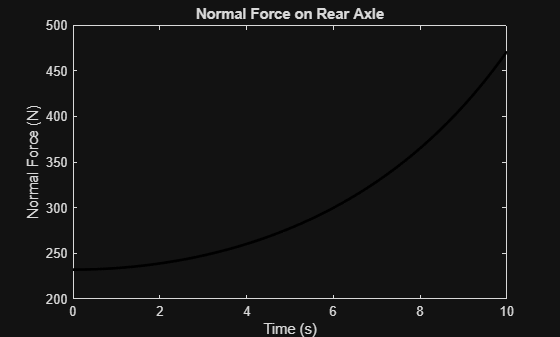


figure;
plot(Time, Normal_Force, 'k', 'LineWidth', 2);
title('Normal Force on Rear Axle');
xlabel('Time (s)');
ylabel('Normal Force (N)');